cd(fileparts(matlab.desktop.editor.getActiveFilename))

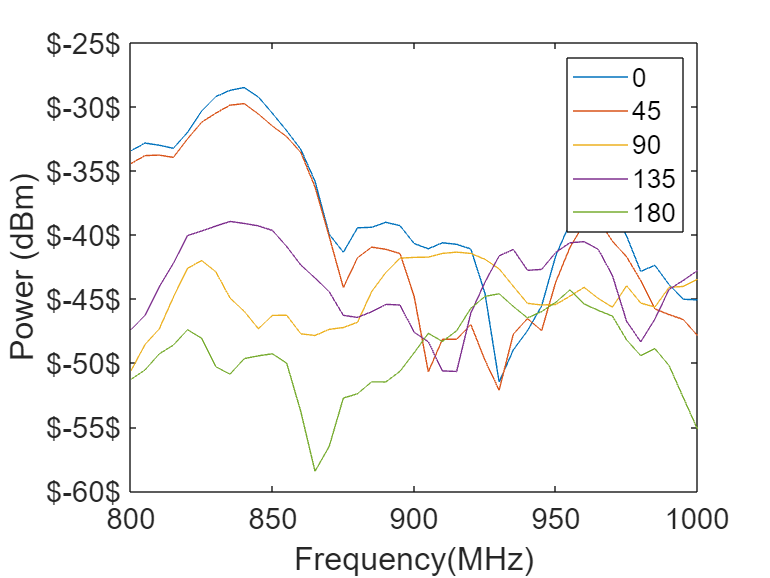

p1raw=csvread('0.csv',2,2);
p2raw=csvread('covered.csv',2,2);
p3raw=csvread('45.csv',2,2);
p4raw=csvread('90.csv',2,2);
p5raw=csvread('135.csv',2,2);
p6raw=csvread('180.csv',2,2);
p1=[];
p2=[];
p3=[];
p4=[];
p5=[];
p6=[];

for i=1:41;
    p1(i)=p1raw(1+15*(i-1));
    p2(i)=p2raw(1+15*(i-1));
    p3(i)=p3raw(1+15*(i-1));
    p4(i)=p4raw(1+15*(i-1));
    p5(i)=p5raw(1+15*(i-1));
    p6(i)=p6raw(1+15*(i-1));
end

csvwrite('1.csv',p1');
csvwrite('6.csv',p6');

fre=800:5:1000;

plot(fre,p1);
hold on;
plot(fre,p3);
hold on;
plot(fre,p4);
hold on;
plot(fre,p5);
hold on;
plot(fre,p6);
hold on;
legend('0','45','90','135','180');
xlabel('Frequency(MHz)');
ylabel('Power (dBm)');

yticklabels(arrayfun(@(x) sprintf('$%d$', x), -60:5:-25, 'UniformOutput', false))
ax = gca;
ax.FontSize = 16;